m = 100;
r_domain = linspace(0,2,m);
theta_domain = linspace(0,2*pi,m);
[x_domain,y_domain] = pol2cart(theta_domain,r_domain);

Omega_x = meshgrid(x_domain);
Omega_y = meshgrid(y_domain)';

syms n odd
syms r theta x y

fund_sol = 2^(1-n)/(pi*n)*r^n*sin(n*theta)

$$fund\_sol = \frac{0.3183\,\frac{1}{2^{n-1}}\,r^{n}\,\sin\left(n\,\theta \right)}{n}$$

fund_sol(x,y,n) = subs(fund_sol,[r theta], [sqrt(x^2 + y^2) atan2(y,x)])

$$fund\_sol(x, y, n) = \frac{0.3183\,\frac{1}{2^{n-1}}\,\sin\left(n\,\text{atan2}\left(1\,y,x\right)\right)\,{\left(x^{2}+y^{2}\right)}^{0.5000\,n}}{n}$$

U_sym = symsum(fund_sol,n,1,10) + 0.5;
U_fun = matlabFunction(U_sym)

U_fun = function_handle with value:
    @(x,y)(sin(atan2(y,x).*2.0).*(x.^2+y.^2))./(pi.*4.0)+(sin(atan2(y,x).*4.0).*(x.^2+y.^2).^2)./(pi.*3.2e+1)+(sin(atan2(y,x).*3.0).*(x.^2+y.^2).^(3.0./2.0))./(pi.*1.2e+1)+(sin(atan2(y,x).*6.0).*(x.^2+y.^2).^3)./(pi.*1.92e+2)+(sin(atan2(y,x).*5.0).*(x.^2+y.^2).^(5.0./2.0))./(pi.*8.0e+1)+(sin(atan2(y,x).*8.0).*(x.^2+y.^2).^4)./(pi.*1.024e+3)+(sin(atan2(y,x).*1.0e+1).*(x.^2+y.^2).^5)./(pi.*5.12e+3)+(sin(atan2(y,x).*7.0).*(x.^2+y.^2).^(7.0./2.0))./(pi.*4.48e+2)+(sin(atan2(y,x).*9.0).*(x.^2+y.^2).^(9.0./2.0))./(pi.*2.304e+3)+(sqrt(x.^2+y.^2).*(imag(x)+real(y)))./(pi.*abs(x+y.*1i))+1.0./2.0


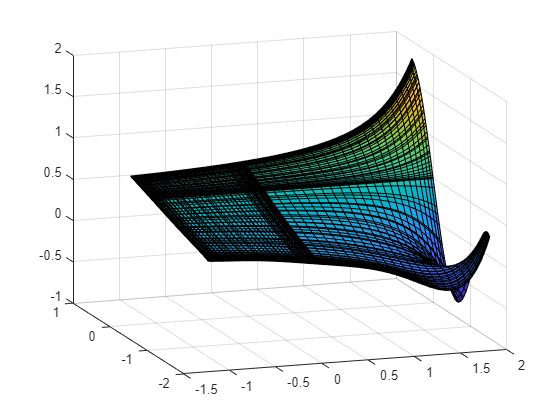


U_fun_dat = U_fun(Omega_x,Omega_y);

figure
surf(Omega_x,Omega_y,U_fun_dat)